%先把列含义改为xyz 名
FJ11 = csvread('FJ11.csv');
FJ3 = csvread('FJ3.csv');

% 将表格转换为结构体
%FJ11_struct = table2struct(FJ11);
%FJ3_struct = table2struct(FJ3);
% 保存为 .mat 文件
%save('FJ11.mat', 'FJ11_struct');
%load('FJ11.mat')
%save('FJ3.mat', 'FJ3_struct');
%load('FJ3.mat')
%load('FJ12.mat')
R = 300.4;
%ddF = 0.2713:0.001:0.2913;%焦点P坐标变化量
ddF = 0.2713:0.001:0.3322;

for e=1:length(ddF)
    F=0.466*R+ddF(e);
    %dF=0.31:0.001:0.33;%理想抛物面顶点K坐标变化量
    dF=0.31:0.001:0.33;
    w=10000000000;
    a=0;
    for i=1:length(dF)
        %length函数返回矩阵中最大的维度的长度
        f=dF(i)+F;%抛物面顶点到焦点的距离
        c=-4*f*(R+dF(i));
        n=1;
        for j=1:length(FJ11)
            %所以此时是FJ11表格的行数
            r2(j,1)=sqrt((FJ11(j,1))^2+(FJ11(j,2))^2);
            r2(j,2)=FJ11(j,3);
            %sqrt平方根
            %判断是否在300m口径的抛物面上，xy平方和再开根与150相比
            if r2(j,1)<=150 && r2(j,2)<-260.1540
                FJ111(n,1)=FJ11(j,1);
                FJ111(n,2)=FJ11(j,2);
                FJ111(n,3)=FJ11(j,3);
                FJ111(n,4)=FJ11(j,4);
                n=n+1;
            end
        end
        %初步筛选，FJ111是符合的数据
        for k=1:length(FJ111)
            rl(k,1)=sqrt((FJ111(k,1))^2+(FJ111(k,2))^2+(FJ111(k,3))^2);
            sital(k,1)=acos(FJ111(k,3)/rl(k));
            fail(k,1)=atan(FJ111(k,2)/FJ111(k,1));

            a=(sin(sital(k,1)))^2;
            b=-4*f*cos(sital(k,1));

            rl(k,2)=(-b+sqrt(b^2-4*a*c))/(2*a);
            rl(1,2)=dF(i)+rl(1,1);

            rl(k,3)=rl(k,1)-rl(k,2);
            
            %新的xyz
            rl(k,4)=rl(k,2)*sin(sital(k,1))*cos(fail(k,1));
            rl(1,4)=0;
            rl(k,5)=rl(k,2)*sin(sital(k,1))*sin(fail(k,1));
            rl(1,5)=0;
            rl(k,6)=rl(k,2)*cos(sital(k,1));
        end
        r(:,1)=rl(:,3);
        % W 主索节点最大径向调节量
        W(i)=max(max(abs(r)));
        %判断附件3中4300块反射板每一个主索节点是否符合300m要求
        for l=1:3
            for m=1:4300
                %ismember 判断FJ3中哪些元素存在于FJ111，存在返回1
                %比如m=1，就是FJ3（1，1）这个元素是否在FJ111第四列中
                x(m)=ismember(FJ3(m,l),FJ111(:,4));
                %FJ4就是将FJ3不在FJ111上的点变为0
                if x(m)>0
                    FJ4(m,l)=FJ3(m,l);
                else
                    FJ4(m,l)=0;
                end
            end
        end

        tz1(:,1:3)=FJ111(:,1:3);%原xyz
        tz2(:,1:3)=rl(:,4:6);%加dF后的xyz
        tz1=tz1./abs(tz1);

        tz1(isnan(tz1))=1;%将所有nan替换成1
        tz2=abs(tz2).*tz1;%有点像平方

        rl(:,4:6)=tz2(:,1:3);
        for M=1:length(FJ4)
            if FJ4(M,1)>5 && FJ4(M,2)>5 && FJ4(M,3)>5
                %比如M=1，A A1 A2是一块反射板的三个主索节点在FJ111表格的位置
                %然后求这三个点之间的距离，以及变化后的距离
                %返回的是该点在FJ111矩阵中的位置
                [A,B]=find(FJ111(:,4)==FJ4(M,1));
                [A1,B1]=find(FJ111(:,4)==FJ4(M,2));
                [A2,B2]=find(FJ111(:,4)==FJ4(M,3));
                
                %这是求原本两个点之间的距离分别是1和2 1和3 2和3
                len(M,1)=sqrt((FJ111(A,1)-FJ111(A1,1))^2+(FJ111(A,2)-FJ111(A1,2))^2+(FJ111(A,3)-FJ111(A1,3))^2);
                len(M,2)=sqrt((FJ111(A,1)-FJ111(A2,1))^2+(FJ111(A,2)-FJ111(A2,2))^2+(FJ111(A,3)-FJ111(A2,3))^2);
                len(M,3)=sqrt((FJ111(A1,1)-FJ111(A2,1))^2+(FJ111(A1,2)-FJ111(A2,2))^2+(FJ111(A1,3)-FJ111(A2,3))^2);

                %这是求变化后两点间的距离
                len1(M,1)=sqrt((rl(A,4)-rl(A1,4))^2+(rl(A,5)-rl(A1,5))^2+(rl(A,6)-rl(A1,6))^2);
                len1(M,2)=sqrt((rl(A,4)-rl(A2,4))^2+(rl(A,5)-rl(A2,5))^2+(rl(A,6)-rl(A2,6))^2);
                len1(M,3)=sqrt((rl(A1,4)-rl(A2,4))^2+(rl(A1,5)-rl(A2,5))^2+(rl(A,6)-rl(A2,6))^2);

                %求lamda
                det(M,1)=abs(len1(M,1)-len(M,1))/len(M,1);
                det(M,2)=abs(len1(M,2)-len(M,2))/len(M,2);
                det(M,3)=abs(len1(M,3)-len(M,3))/len(M,3);

            end
        end
        dete(i)=min(max(det));%一次max是找列向量的最大值，两次是全部的
        lv(i)=abs(sum(len)-sum(len1))/sum(len);
        if dete(i)<=w
            w=dete(i);
            cc=W(i);
            o=dF(i)+R;
            ol=rl;
            oo=0.534*R-ddF(e);
            ooo=det;
            oooo=lv(i);
            aa=1-sum(sum(ooo>0.0007))/numel(ooo);
           
            di=tz2;
            dii=det;

        end
        
    end
end

disp('理想抛物面顶点距离原点长度为：')

理想抛物面顶点距离原点长度为：


disp(o)

  300.7100



disp('焦点距离原点长度为：')

焦点距离原点长度为：


disp(oo)

  160.0823



disp('促动器最大伸缩量为：')

促动器最大伸缩量为：


disp(cc)

    0.3530



disp('将基础球面调节至理想抛物面节点间距离最大变化幅度：')

将基础球面调节至理想抛物面节点间距离最大变化幅度：


disp(w)

    0.0011



disp('所有节点间距离整体变化幅度：')

所有节点间距离整体变化幅度：


disp(oooo)

    0.0049



disp('节点间距离变化幅度合格率：')

节点间距离变化幅度合格率：


disp(aa)

    0.4095



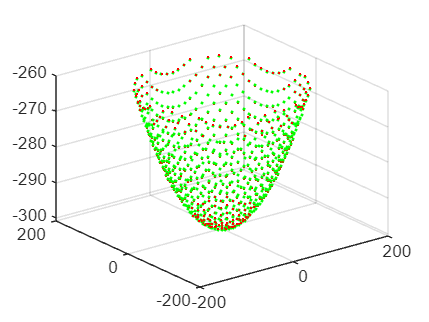


x3=di(:,1);
y3=di(:,2);
z3=di(:,3);
scatter3(x3,y3,z3,3,'*','g')
hold on
x1=FJ111(:,1);
y1=FJ111(:,2);
z1=FJ111(:,3);
scatter3(x1,y1,z1,15,'.','r')

%以下为对变化幅度不满足条件的主索节点编号的记录
for Y=1:3
    for X=1:length(dii)
        if dii(X,Y)>0.0007
            diii(X,Y)=1;
        else
            diii(X,Y)=0;
        end
    end
end

for t=1:length(dii)
    if diii(t,1)>0
        MA(t,1)=FJ4(t,1);
        MA(t,2)=FJ4(t,2);
    end
    if diii(t,2)>0
        MA(t,2)=FJ4(t,2);
        MA(t,3)=FJ4(t,3);
    end
    if diii(t,3)>0
        MA(t,1)=FJ4(t,1);
        MA(t,3)=FJ4(t,3);
    end
end